# ParTI Analysis on Single Cell SCLC Cell Lines (RNAseq)

We read in MAGIC imputed single cell data from 2-Human_cell_lines_scPCHA.ipynb. We used GeoSketch to downsample the data to make the analysis more efficient.

clear all 
% Shown to be best number of archetypes by elbow plot from py_pcha
nArchetypes = 6;

global ForceNArchetypes; ForceNArchetypes = nArchetypes;

% % Instead of setting this at the beginning of the code, I am going to run a
% % for loop later to iterate over different values and these will be

% % reset.
% random_int = randi(1000000)
% outputFileName = sprintf('%d',random_int)
% algNum = 5
% dim = 12
% binSize = 0.1 


% Load the data into Matlab from a comma separated value (CSV) file
% The file is a purely numerical matrix, with patients as rows and genes as
% columns;
inputPath = '/Users/smgroves/Documents/Github/Groves-CellSys2021/notebooks/out/cell-lines/';
origPath = pwd;
geneExpression = dlmread(strcat(inputPath,'downsampled_X_magic_for_ParTI.csv'), ',');
% geneExpression = geneExpression'
% The file is formated as samples (i.e. patients) x genes. 
% We load gene names.
geneNames = importdata(strcat(inputPath,'X_magic_for_ParTI_GeneNames.csv'), ',');

## We import the sample attributes, i.e. the clinical data on patients

These come in two kinds: - discrete attributes, i.e. categorical data (citizenship, gender, cancer progression grade, ...) - continuous attributes, i.e. numerical data (weight, age, tumor volume, ...) We start by loading a file with clinical attributes, both discrete and continuous.

cd /Users/smgroves/Documents/Github/Groves-CellSys2021/ParTI;


[discrAttrNames, discrAttr] = ...
    read_enriched_csv(strcat(inputPath,'X_magic_for_ParTI_Attr.csv'), ',');

%where discrAttr is a matrix of patients x attributes. The names of
%the attributes are stored in discrAttrNames.

% Continuous attributes are analysed using a different statistical procedure
% than discrete attributes. We therefore load a file with vectors 'discIdcs' and 
% 'contIdcs' containing the indices of discrete and continuous attributes 
% to be considered in the study:
% load Data/CancerRNAseq/CancerRNAseq_featIdcs.mat;

% We extract continous attributes, discarding the sample ID
% (the order of the clinical records matches that of the expression data)
contIdcs = [1 3 4 5 6 7 9 10];

contIdcs =      1     3     4     5     6     7     9    10


contAttrNames = discrAttrNames(:,contIdcs);
contAttr = discrAttr(:,contIdcs);
% Now we convert contAttr to a matrix of doubles
contAttr = str2double(contAttr);

discIdcs = [2 8];

discIdcs =      2     8


% And select the remaining discrete attributes:
discrAttrNames = discrAttrNames(:,discIdcs);
discrAttr = discrAttr(:,discIdcs);

## We expand the sample attributes by computing changes in GO category expression

This section is optional. It makes it possible to determine broad gene expression categories that are over-expressed in the vicinity of archetypes. This is helpful to characterize the archetypes.


[GOExpression,GONames,~,GOcat2Genes] = MakeGOMatrix(geneExpression, geneNames, ...
                {'MSigDB/c5.go.bp.v7.2.symbols.gmt'}, ...
                10);
% GOExpression is a matrix of patients x GO categories, and
% GONames contains the name of the GO categories.
% GOcat2Genes is a boolean matrix of genes x GO categories which
% indicates, for each category, which genes were used to compute it.
% In the next line, we expand this matrix so that it has as many columns as
% the number of continuous features (clinical + GO). Because clinical
% features are typically not directly based on specific genes, we add
% zeroes in the corresponding columns:
% GOcat2Genes=[zeros(size(GOcat2Genes,1),size(discrAttr,2)),GOcat2Genes];
% % and we expand the continuous clinical features with GO-based continuous
% % features:
contAttrNames = [contAttrNames, GONames];
contAttr = [contAttr, GOExpression];
% contAttrNames = GONames;
% contAttr = GOExpression;

## Finally, we substitute underscores '_' in variable names with spaces ' '

to prevent the characters following underscores from appearing in indice position.

discrAttrNames = regexprep(discrAttrNames, '_', ' ');
contAttrNames = regexprep(contAttrNames, '_', ' ');

% [arc_lite, arcFinal, pc_lite] = ParTI_lite(geneExpression, 5, 60, discrAttrNames, ...
%  discrAttr, 0, contAttrNames, contAttr, [], 0.05, 'c5');
outPath = strcat(origPath, sprintf('/out/%d',nArchetypes))

outPath = '/Users/smgroves/Documents/GitHub/Groves-CellSys2021/notebooks/ParTI-code/single-cell/cell-lines/out/6'

Converting discrete features to booleans
Starting to perform PCA, for big data on slow computers this may take a while...


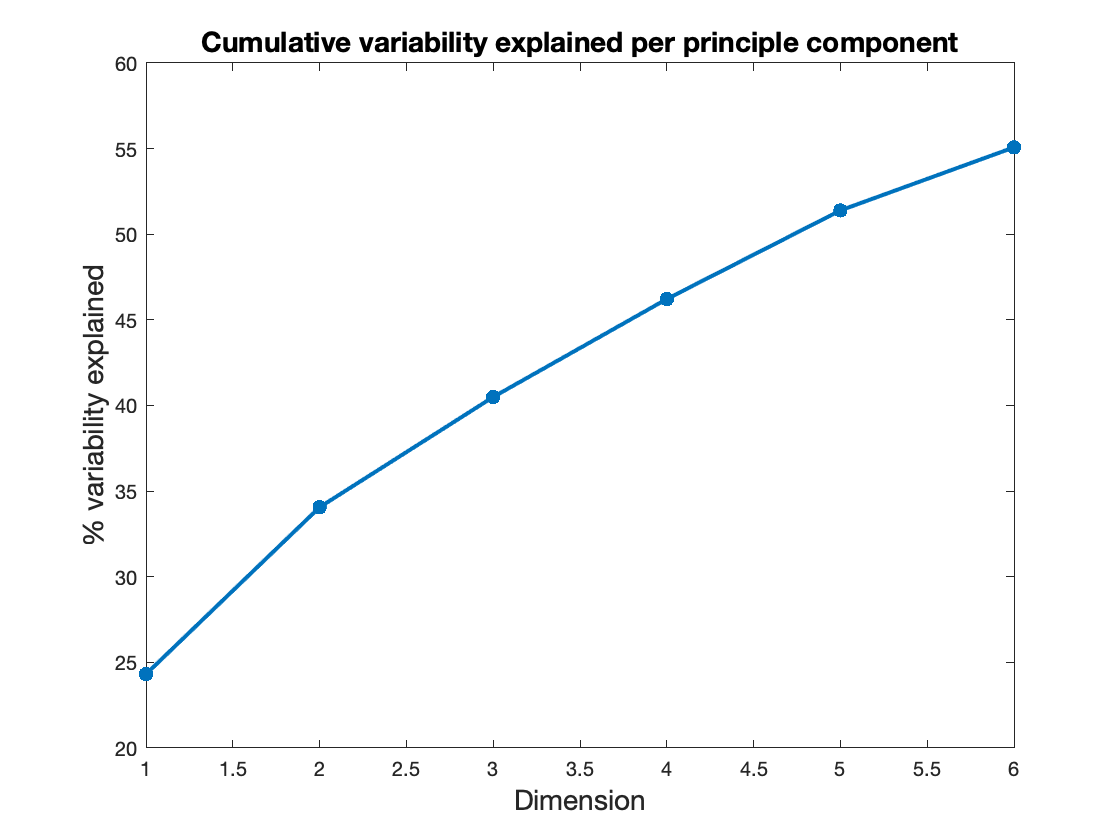

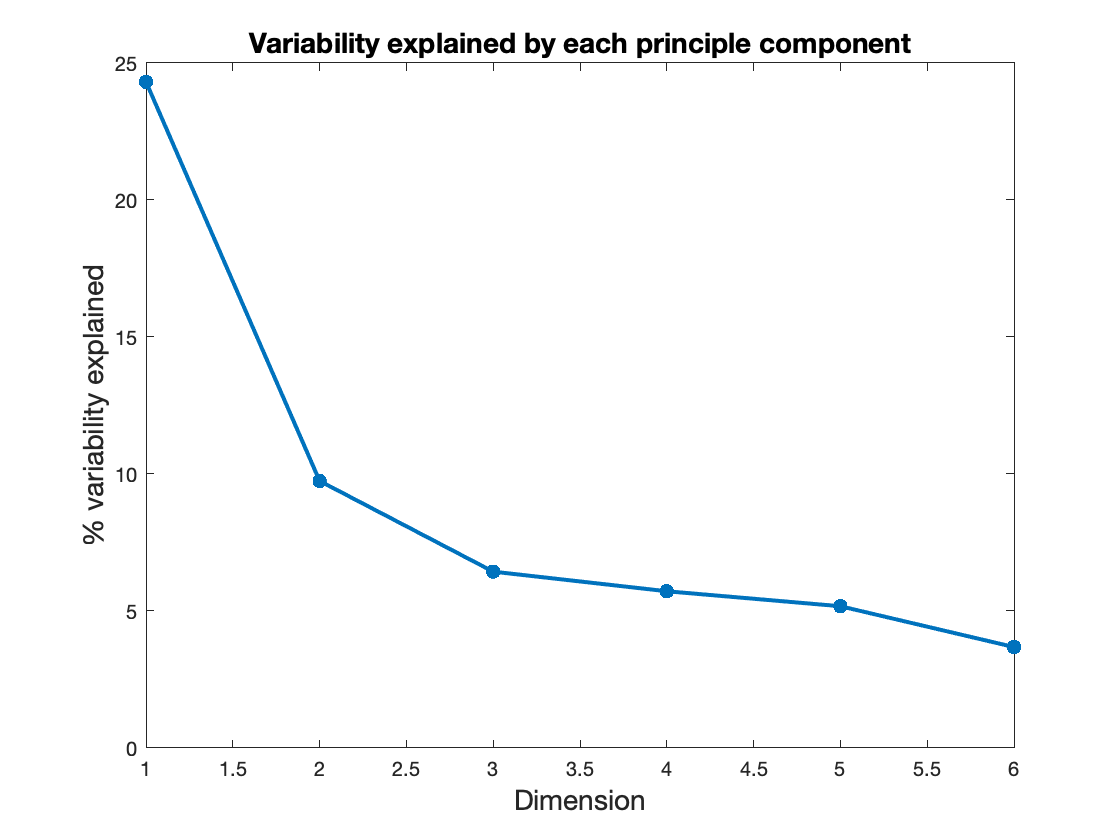

Calculating explained variance with PCHA (Morup M, Hansen KL, 2011)


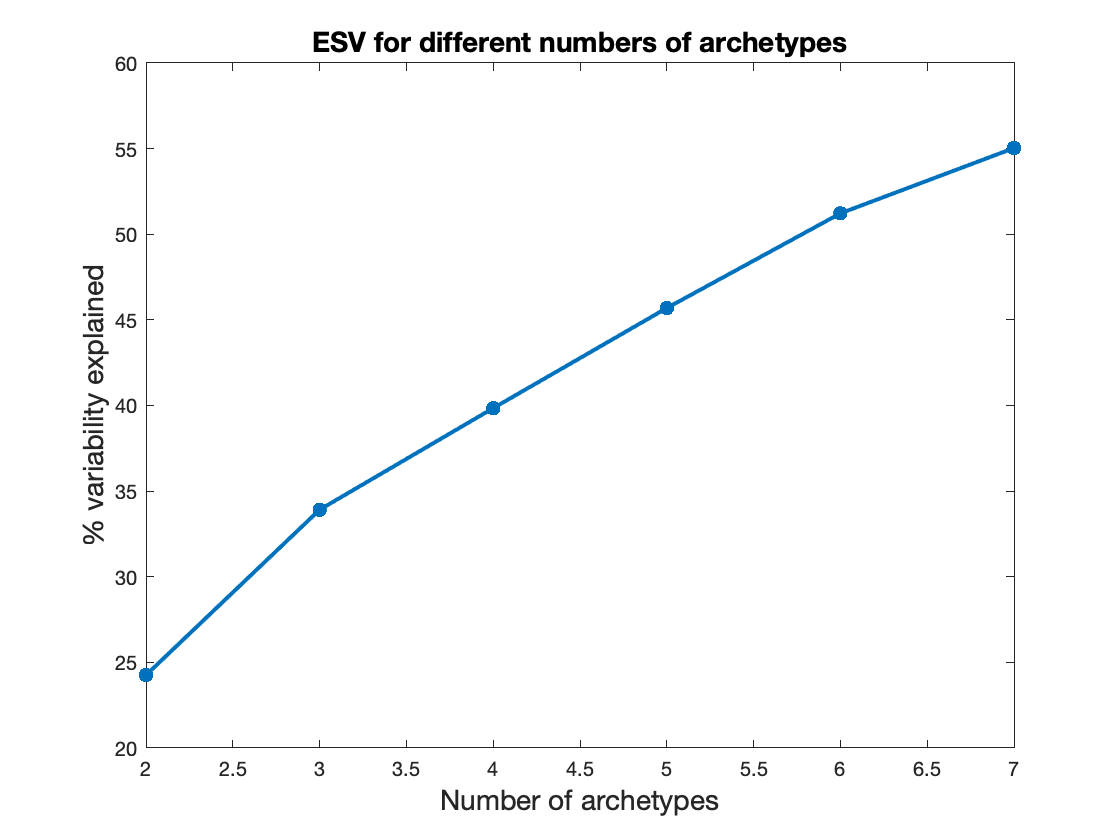

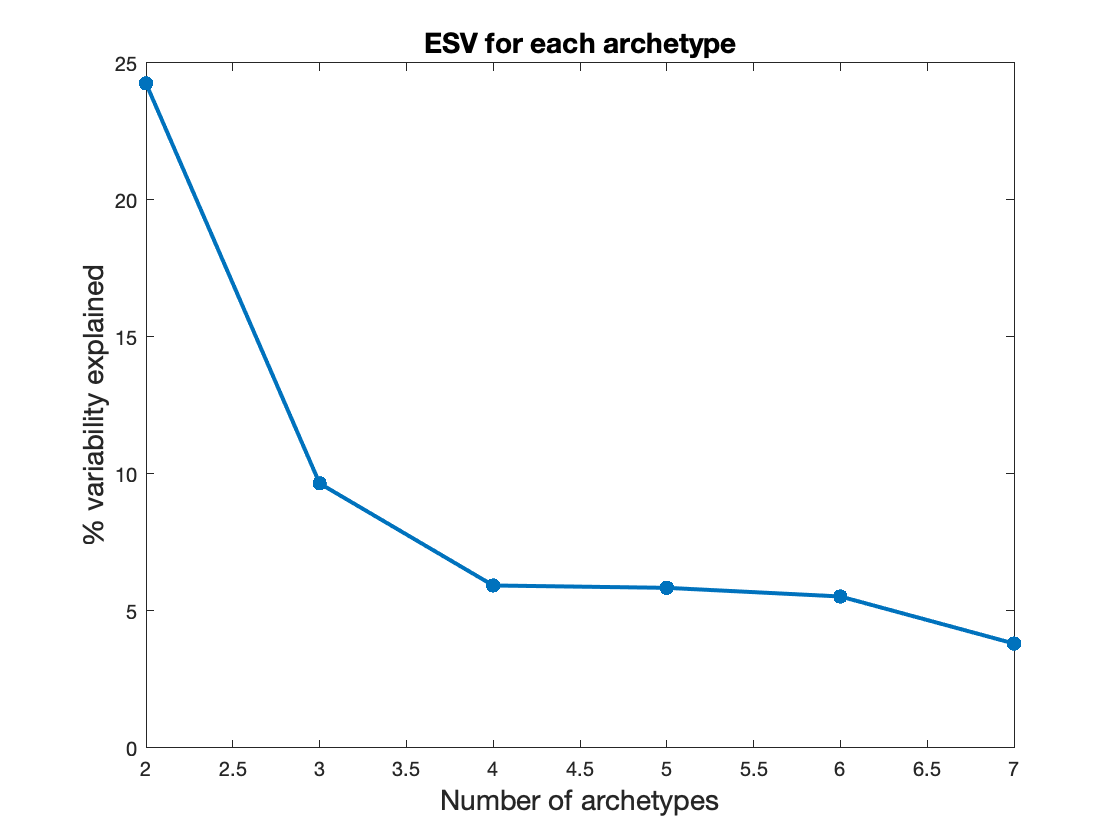

Warning! ForceNArchetypes preset in workspace to 6. Will now use that value.
Calculating archetypes positions with PCHA (Morup M & Hansen LK, 2011)
finished finding the archetypes


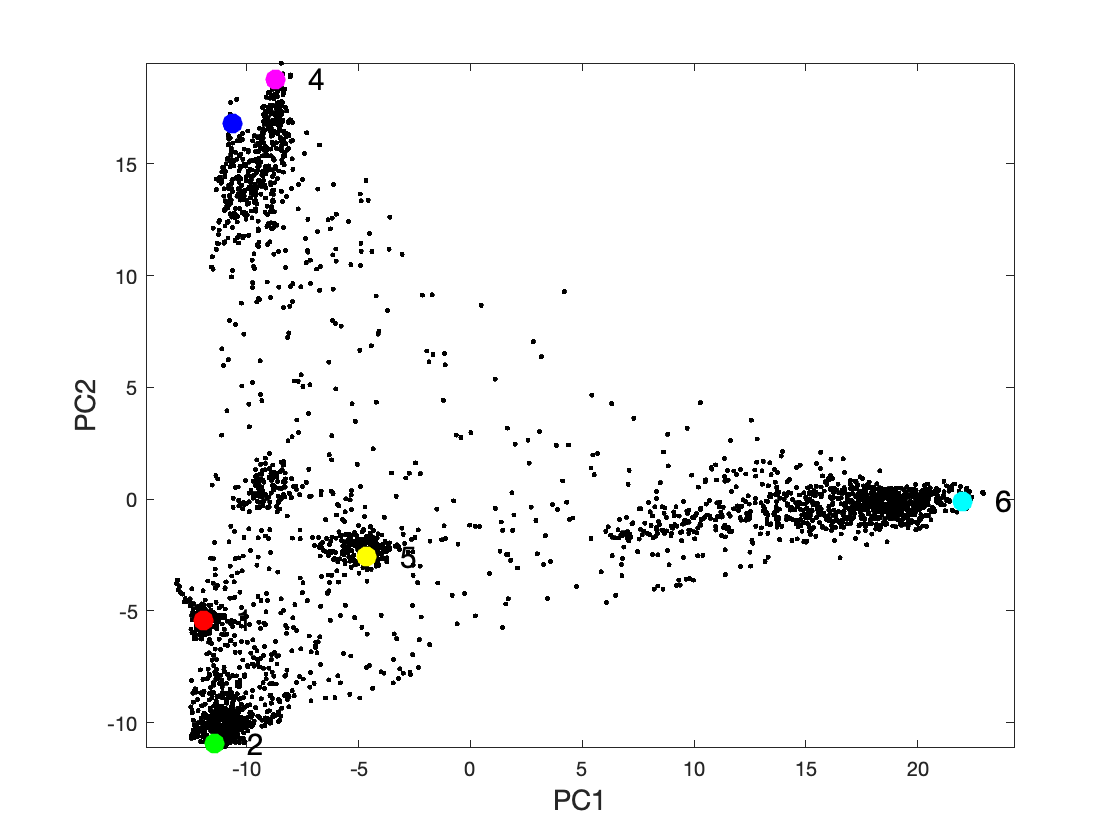

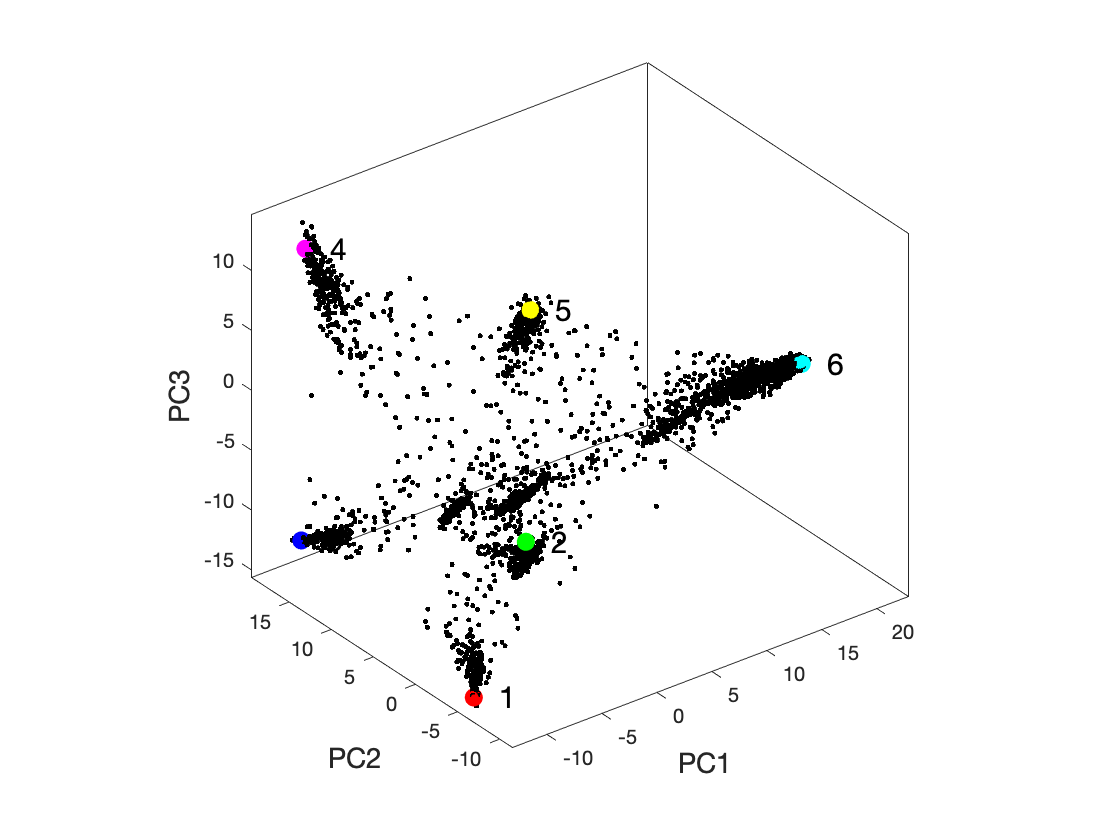

Skipping enrichment analysis as no features were provided.


if ~exist(outPath, 'dir')
    mkdir(outPath);
end
if exist(strcat(outPath, '/arcs_dims.csv'), 'file') == 2
    fprintf('Reloading previously computed archetypes\n');
    load(strcat(outPath, '/arcs_dims.csv'))
    arc = arcs_dims;
    load(strcat(outPath, '/arcsOrig_genes.csv'))
    arcOrig = arcsOrig_genes;
else 
    [arc, arcOrig, pc, coefs1] = ParTI_lite(geneExpression, 5, ForceNArchetypes); 
    %[arc, arcOrig, pc, errs, pval, coefs1] = ParTI(geneExpression);
%     save(strcat(origPath, '/out/arcs_dims.tsv'), 'arc', '-ascii')
    csvwrite(strcat(outPath, '/arcs_dims.csv'), arc)
%     save(strcat(origPath, '/out/arcsOrig_genes.tsv'), 'arcOrig', '-ascii')
    csvwrite(strcat(outPath, '/arcsOrig_genes.csv'), arcOrig)
    %save(strcat(origPath, '/pcsOrig_samplesXdims.tsv'), 'pc', '-ascii')
    csvwrite(strcat(outPath, '/pcsOrig_samplesXdims.csv'), pc)
    %save(strcat(origPath, '/projOrig_varsXdims.tsv'), 'coefs1', '-ascii')
    csvwrite(strcat(outPath, '/projOrig_varsXdims.csv'), coefs1)
%     csvwrite(strcat(origPath, '/out/arcs_errs.csv'), errs)
%     csvwrite(strcat(origPath, '/out/arcs_pval.csv'), pval)
end


clear pc coefs1 errs pval;


### Run full ParTI analysis (with t ratio calculation) on 6 archetypes

Starting to perform PCA, for big data on slow computers this may take a while...


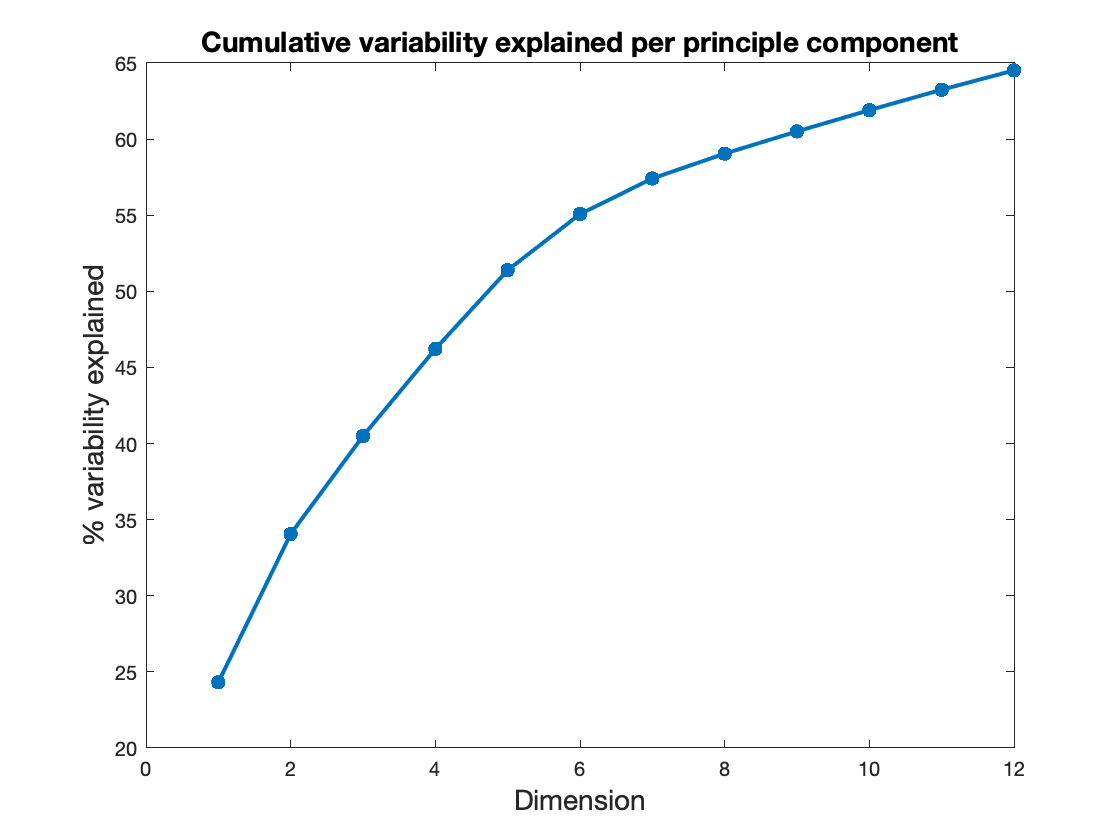

Calculating explained variance with PCHA (Morup M, Hansen KL, 2011)


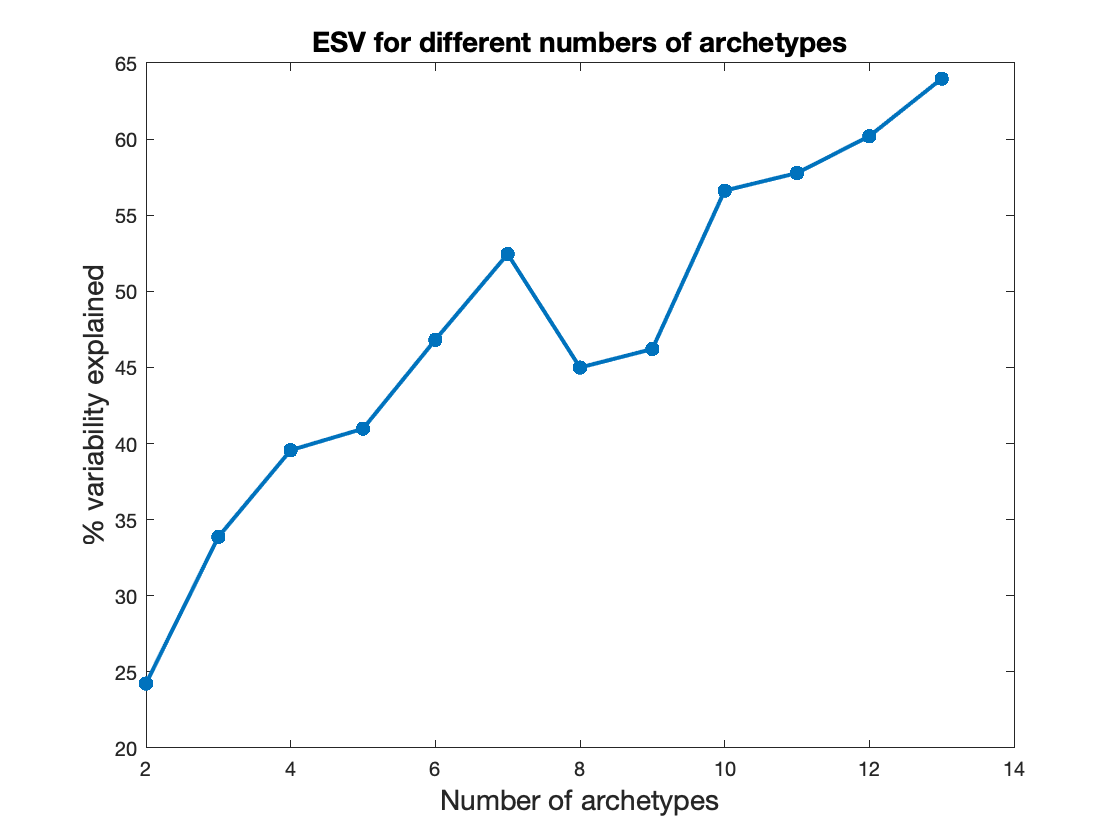

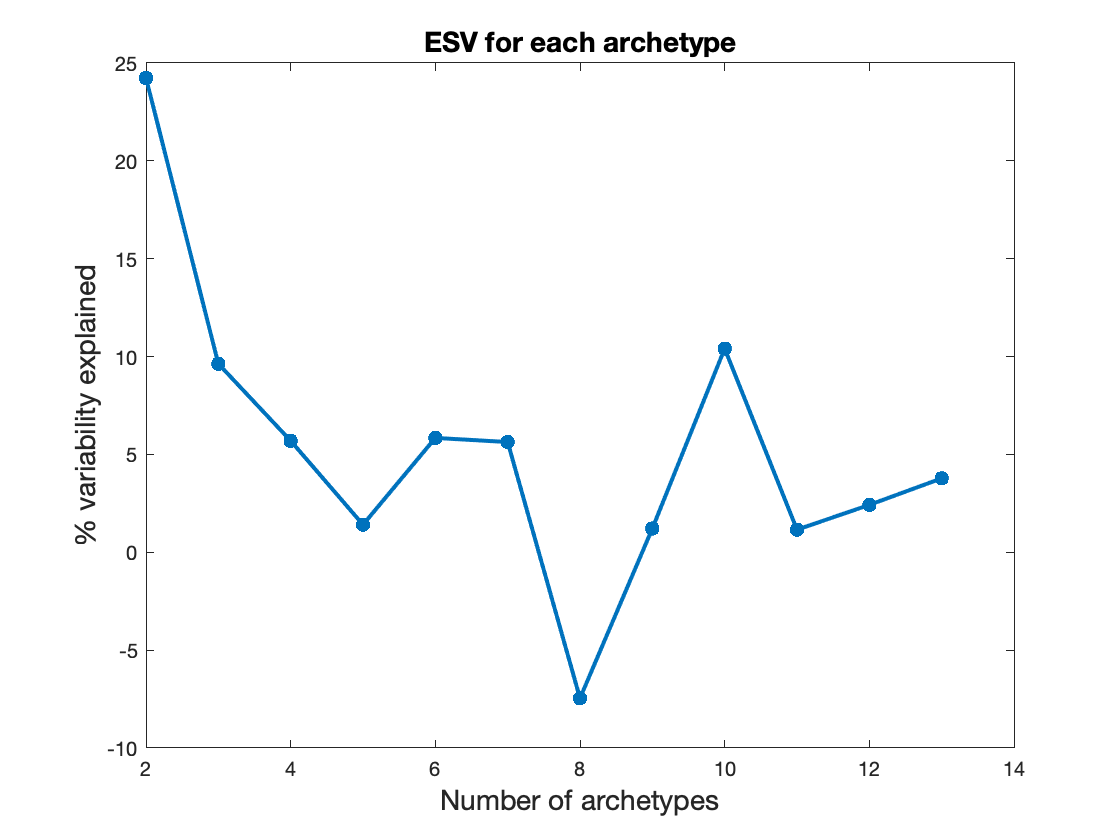

Warning! ForceNArchetypes preset in workspace to 6. Will now use that value.
Calculating archetypes positions with PCHA (Morup M & Hansen LK, 2011)
finished finding the archetypes
Now computing t-ratios.
10% done
20% done
30% done
40% done
50% done
60% done
70% done
80% done
90% done
100% done
The significance of 6 archetypes has p-value of: 0.00000 
Now calculating errors on the archetypes.
10% done
20% done
30% done
40% done
50% done
60% done
70% done
80% done
90% done
100% done
finished finding the archetypes error distribution


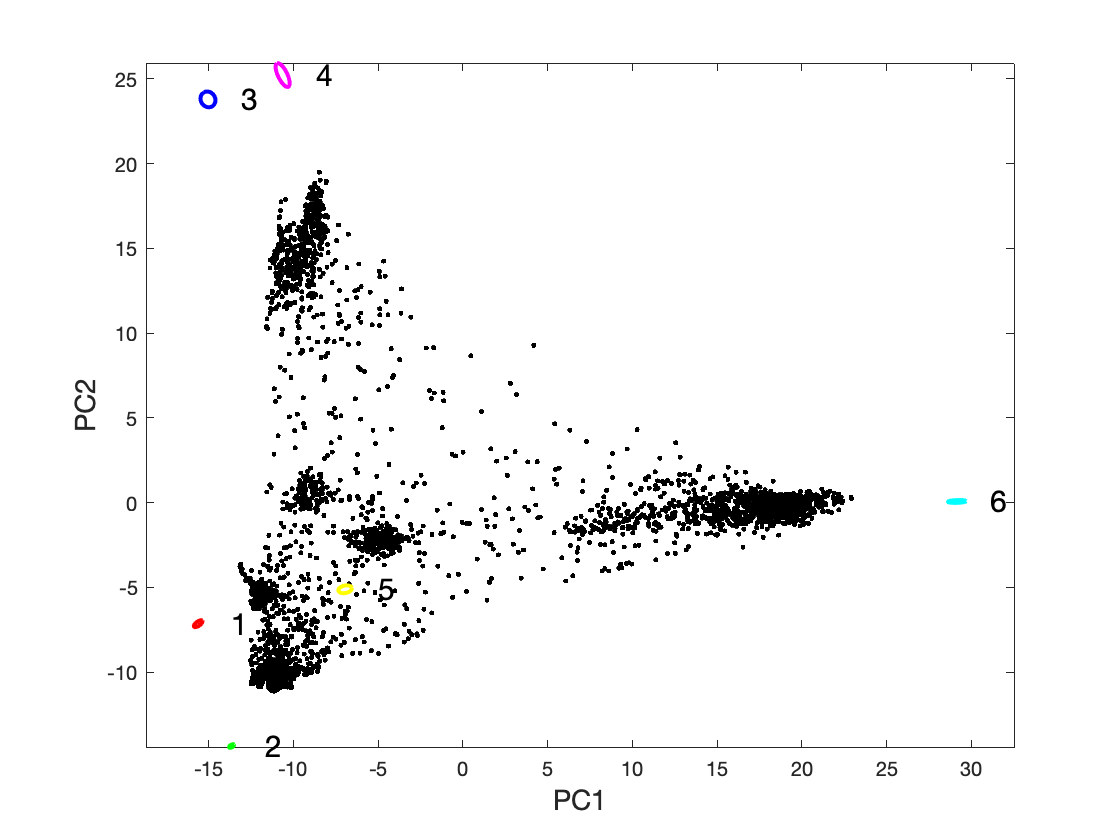

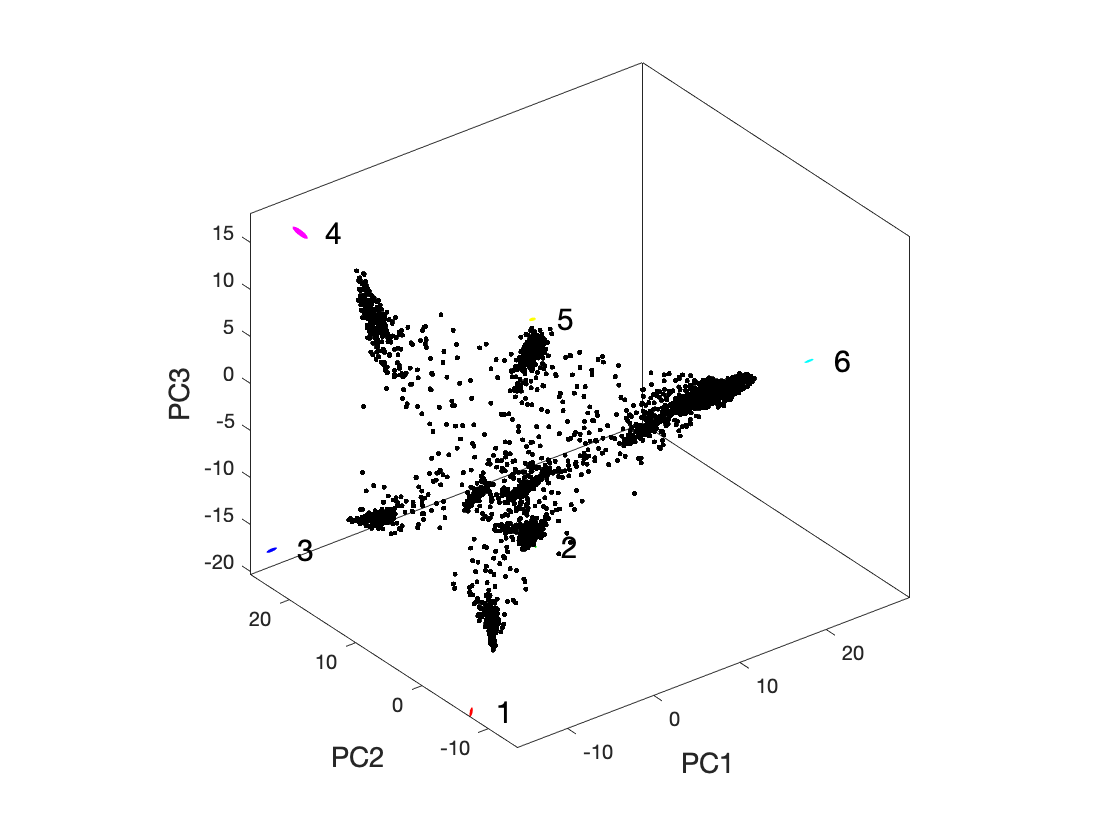

Finished sorting data points.
Your data was divided into 10 bins.


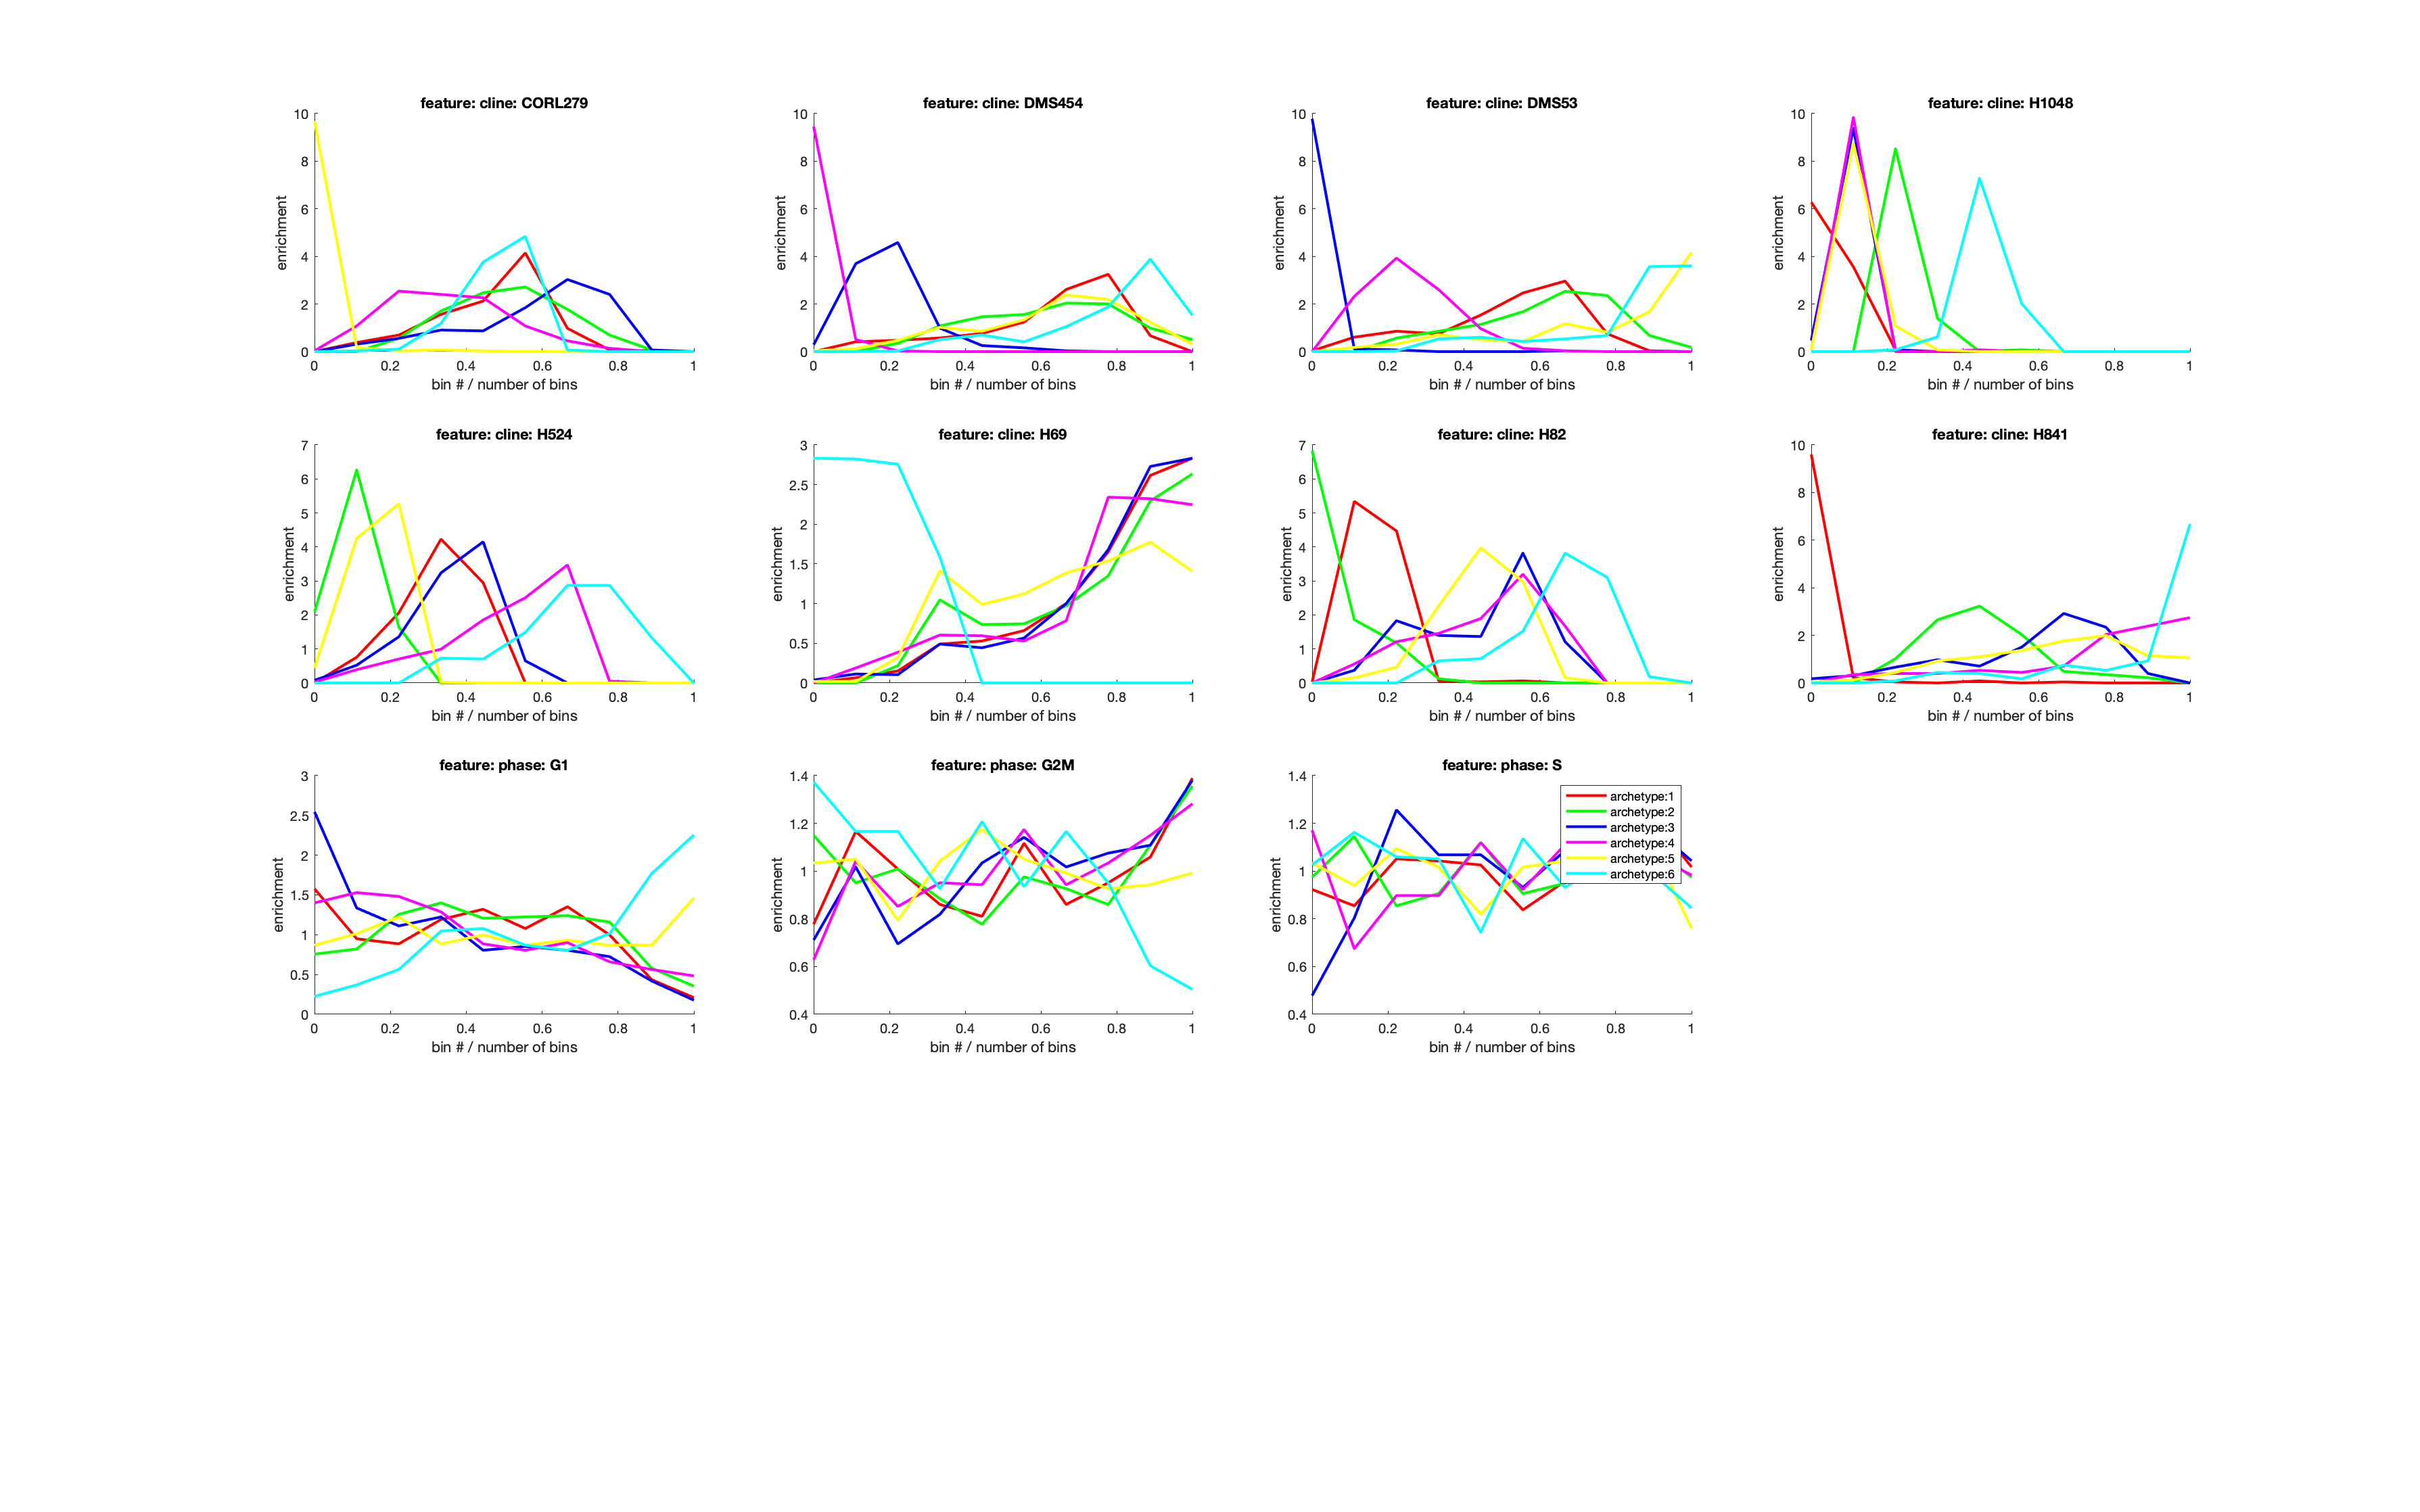

Finished computing discrete enrichments.
Finished computing continuous enrichments.
Now applying leave-one-out to verify robustness enrichment of GO categories
5% done
10% done
15% done
20% done
25% done
30% done
35% done
40% done
45% done
50% done
55% done
60% done
65% done
70% done
75% done
80% done
85% done
90% done


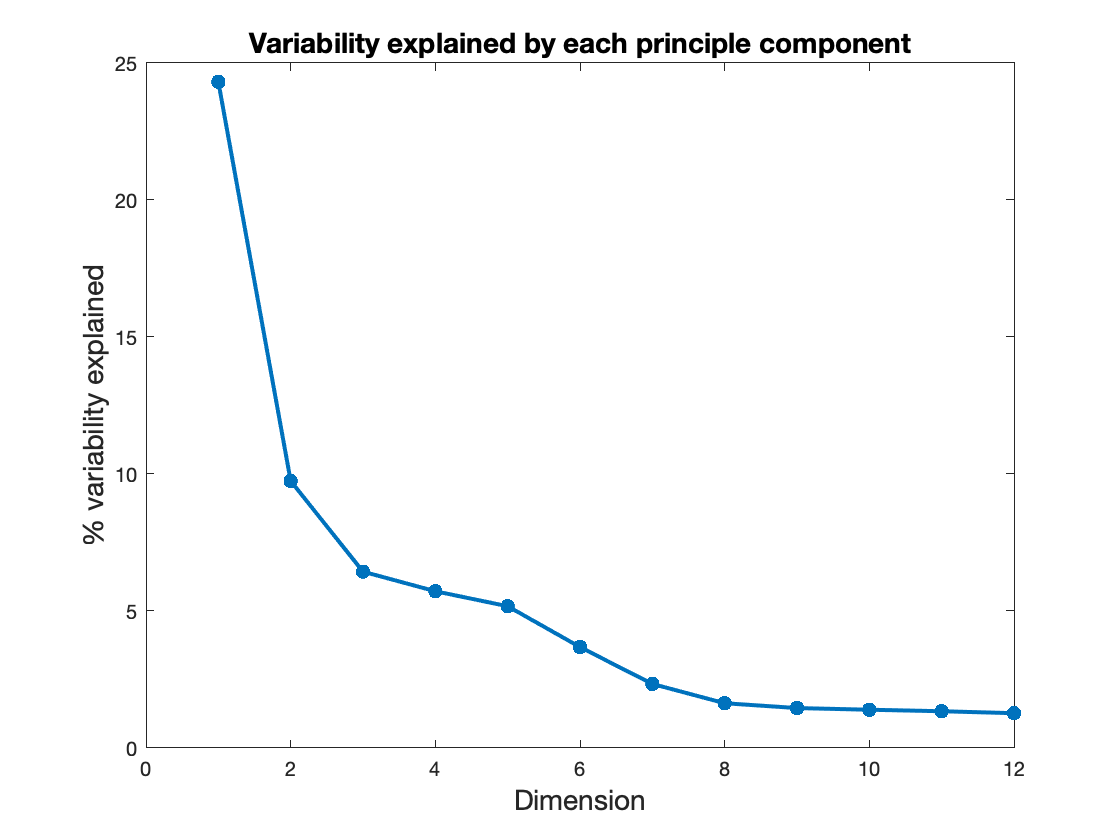

95% done
100% done


Index in position 2 exceeds array bounds (must not exceed 4984).

Error in GoCategoriesLeaveOneOut (line 40)
    indGo2Genes=GOcat2Genes(:,i);

Error in calculateEnrichment (line 79)
    isSignificantL1o=GoCategoriesLeaveOneOut(sigGOind,GOcat2Genes,DataPointsOrg,NArchetypes,algNum,numIter,EnMatCont,binSize);

Error in <a


dim = 12;
binSize = 0.1 ;
random_int = randi(1000000);
outputFileName = sprintf('%d',random_int);
outPath = strcat(origPath, sprintf('/out/%d',nArchetypes));
[arc, arcFull, pc, errs, pval, coefs, P, tRatioRand, tRatioReal] = ParTI(geneExpression, 5, dim, discrAttrNames, ...
discrAttr, 0, contAttrNames, contAttr,GOcat2Genes, binSize, strcat(outPath,'/', outputFileName));

fid = fopen(strcat(origPath,'/params.txt'), 'a+');
fprintf(fid, '%d, %d, %d, %d, %d,%d, %d\n', random_int,algNum,dim,binSize, nArchetypes, pval, tRatioReal);
fclose(fid);
csvwrite(strcat(outPath,sprintf('/%s_arc.csv',outputFileName)), arc);
csvwrite(strcat(outPath,sprintf('/%s_pc.csv',outputFileName)), pc);
csvwrite(strcat(outPath,sprintf('/%s_arc_full.csv',outputFileName)), arcFull);
csvwrite(strcat(outPath,sprintf('/%s_errs.csv',outputFileName)), errs);
csvwrite(strcat(outPath,sprintf('/%s_coefs.csv',outputFileName)), coefs);
csvwrite(strcat(outPath,sprintf('/%s_tRatioRand.csv',outputFileName)), tRatioRand);

clear arc arcFull pc errs pval coefs P tRatioRand tRatioReal

nArchetypes = 6;

nArchetypes = 5

ForceNArchetypes = nArchetypes;

ForceNArchetypes = 5

outPath = strcat(origPath, sprintf('/out/%d',nArchetypes));

outPath = '/Users/smgroves/Documents/GitHub/Groves-CellSys2021/notebooks/ParTI-code/human-cell-lines/out/5'


ParTI_lite(geneExpression, 1, size(arcOrig,1), [], ...
     [], 0, geneNames, geneExpression, [], binSize, ...
     strcat(outPath, '/geneEnrichment'), arcOrig);

Converting discrete features to booleans
Will use archetypes passed as argument instead of determining them from scratch.
Finished sorting data points.
Finished computing discrete enrichments.
Finished computing continuous enrichments.
*** Wrote summary of enriched continuous features to /Users/smgroves/Documents/GitHub/Groves-CellSys2021/notebooks/ParTI-code/human-cell-lines/out/5/geneEnrichment_continuous_significant.csv


Starting to perform PCA, for big data on slow computers this may take a while...
Calculating explained variance with PCHA (Morup M, Hansen KL, 2011)
Warning! ForceNArchetypes preset in workspace to 3. Will now use that value.
Calculating archetypes positions with PCHA (Morup M & Hansen LK, 2011)
finished finding the archetypes
Now computing t-ratios.


ParTI_lite(geneExpression, 1, size(arcOrig,1), [], ...
     [], 0, geneNames, geneExpression, [], binSize, ...
     strcat(outPath, '/geneEnrichment'), arcOrig);


## Running ParTI in a loop over algorithm, nArchetypes, binSize, and dim


dim = 12;
binSize = 0.1 ;
for nArchetypes = [3 7]
    for algNum = [5]
        ForceNArchetypes = nArchetypes;
        random_int = randi(1000000);
        outputFileName = sprintf('%d',random_int);
        outPath = strcat(origPath, sprintf('/out/%d',nArchetypes));
        [arc, arcFull, pc, errs, pval, coefs, P, tRatioRand, tRatioReal] = ParTI(geneExpression, algNum, dim, discrAttrNames, ...
        discrAttr, 0, contAttrNames, contAttr,GOcat2Genes, binSize, strcat(outPath,'/', outputFileName));
        fid = fopen(strcat(origPath,'/params.txt'), 'a+');
        fprintf(fid, '%d, %d, %d, %d, %d,%d, %d\n', random_int,algNum,dim,binSize, nArchetypes, pval, tRatioReal);
        fclose(fid);
        csvwrite(strcat(outPath,sprintf('/%s_arc_full.csv',outputFileName)), arcFull);
        csvwrite(strcat(outPath,sprintf('/%s_errs.csv',outputFileName)), errs);
        csvwrite(strcat(outPath,sprintf('/%s_coefs.csv',outputFileName)), coefs);
        csvwrite(strcat(outPath,sprintf('/%s_tRatioRand.csv',outputFileName)), tRatioRand);
    
        clear arc arcFull pc errs pval coefs P tRatioRand tRatioReal
    end
end